## **Przetwarzanie Sygnałów Cyfrowych**

# **Parametry sygnalow cyfrowych**

## Jan Rosa 410269 AiR

### Wstęp

### 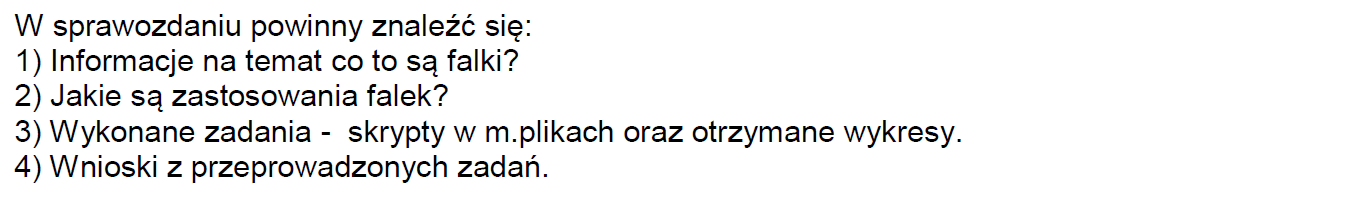

### Zad 1

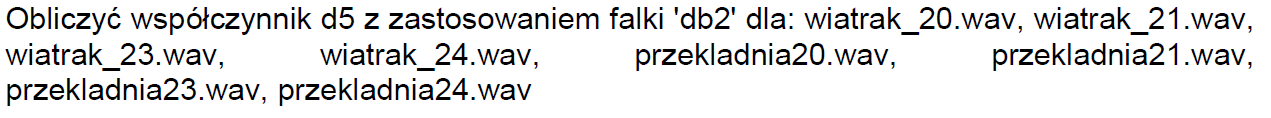

clear all;
files_names = ["wiatrak_20.wav"; "wiatrak_21.wav"; 'wiatrak_23.wav'; 'wiatrak_24.wav'; 'przekladnia20.wav'; 'przekladnia21.wav'; 'przekladnia23.wav'; 'przekladnia24.wav'];
files = [[]];
for i = 1:size(files_names)
    [data, fz] = audioread(files_names(i));
    files(i,:) = data;
end
clear data;
clear i;

d5_vec = [];
for i = 1:size(files)
data = files(i);
[c,l] = wavedec(data,5,'db2');
[d5] = detcoef(c,l,5);
d5_vec(i,:) = d5; 
end
clear d5;
d5_vec'

ans = 1.0e-15 *

   -0.1388    0.0347    0.1388    0.0278    0.0069    0.0833   -0.0833    0.0026
   -0.1388    0.0347    0.1388    0.0278    0.0069    0.0833   -0.0833    0.0026


### Zad 2

Obliczyć współczynnik a4 z zastosowaniem falki 'coif2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

a7_vec = [];
for i = 1:size(files)
data = files(i);
[c,l] = wavedec(data,4,'coif2');
[a7] = appcoef(c,l,'coif2',4);
a7_vec(i,:) = a7; 
end
clear a7;
a7_vec'

ans =     1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355
    1.2546   -0.3247   -1.2747   -0.8269   -0.2056   -0.9753    0.8242   -0.0355


### Zad 3

Obliczyć współczynnik a8 z zastosowaniem falki 'coif2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

### Zad 4

Obliczyć współczynnik d10 z zastosowaniem falki 'haar' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

### Zad 5

Obliczyć współczynnik d10 z zastosowaniem falki 'dmey' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

### Zad 6

Obliczyć współczynnik a8 z zastosowaniem falki 'bior3.5' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

### Zad 7

Wykonać dekompozycję obrazu 'wiatrak_20.wav' funkcją wavedec(), waverec(). Do tego celu

zastosować falkę 'coif2'. Następnie zrekonstruować obraz falką 'coif2'. Proszę zaobserwować

różnice. Proszę użyć 12 stopnia dekompozycji.

### Zad 8

Wykonać dekompozycję obrazu 'wiatrak_20.wav' funkcjami wavedec(), waverec(). Do tego

celu zastosować falkę 'coif2'. Następnie zrekonstruować obraz falką 'haar'. Proszę zaobserwować

różnice. Proszę użyć 12 stopnia dekompozycji.

### Zad 9

Obliczyć współczynnik a12 z zastosowaniem falki 'sym2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

### Zad 1

Obliczyć współczynnik d12 z zastosowaniem falki 'sym2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

### Wnioski

1) W jaki sposób zastosować falki do ekstrakcji cech?

2) Jakie parametry falek możemy zmieniać w toolboxie?

3) Czym różnią się współczynniki a1, d1, d2, d3, d4, d5?

4) Czym różni się transformacja falkowa od filtrów?